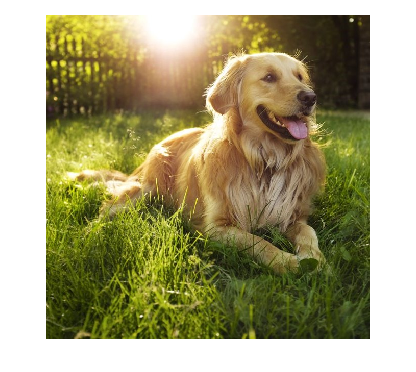

img = imread("squaredog.jpg");
imshow(img);

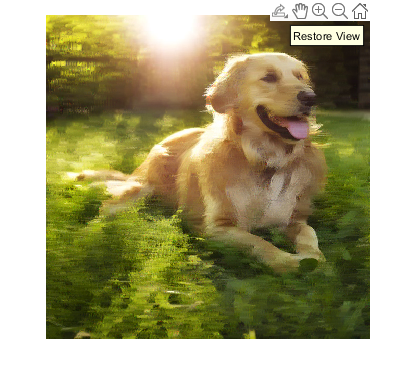


R = im2double(img(:,:,1));
G = im2double(img(:,:,2));
B = im2double(img(:,:,3));


LR = [];
LG = [];
LB = [];

for i = 1:size(R,1)
    LR = [LR,R(i,:)];
    LG = [LG,G(i,:)];
    LB = [LB,B(i,:)];
end

LR = hampel(LR,10,0.8);
LG = hampel(LG,10,0.8);
LB = hampel(LB,10,0.8);

 for i = 1:size(R,1)
     R(i,:) = LR((i-1)*635+ 1: i*635);
     G(i,:) = LG((i-1)*635+ 1: i*635);
     B(i,:) = LB((i-1)*635+ 1: i*635);
 end


outimg = uint8(rescale(cat(3,R,G,B),0,255));
imshow(outimg);